Данные задачи

clear; clc;
syms u v  e f g h;
F1 = e*u.*(1-u) - (  u.*v)/(1+g*u);
F2 = -f*v      + (h*u.*v)/(1+g*u);
F = [F1;F2]

$$F = \left(\begin{array}{c} -e\,u\,\left(u-1\right)-\frac{u\,v}{g\,u+1}\\ \frac{h\,u\,v}{g\,u+1}-f\,v \end{array}\right)$$

%determine parameters of interest
parameters = [e h];
F = subs(F,[f g], [1 1])

$$F = \left(\begin{array}{c} -e\,u\,\left(u-1\right)-\frac{u\,v}{u+1}\\ \frac{h\,u\,v}{u+1}-v \end{array}\right)$$

Поиск неподвижных точек

eqn = 0 == F;
vars = [u,v];
[solu, solv] = solve(eqn,vars);
solutions = [solu solv]

$$solutions = \left(\begin{array}{cc} 0 & 0\\ 1 & 0\\ \frac{1}{h-1} & -\frac{2\,e\,h-e\,h^{2}}{h^{2}-2\,h+1} \end{array}\right)$$

Предельный цикл

divF = divergence(F,vars)

$$divF = \frac{h\,u}{u+1}-e\,u-e\,\left(u-1\right)-\frac{v}{u+1}+\frac{u\,v}{{\left(u+1\right)}^{2}}-1$$

[N D] = numden(divF)

$$N = e-2\,u-v+h\,u-3\,e\,u^{2}-2\,e\,u^{3}+h\,u^{2}-u^{2}-1$$

$$D = {\left(u+1\right)}^{2}$$

N2 = N + 2*e*u^3

$$N2 = e-2\,u-v+h\,u-3\,e\,u^{2}+h\,u^{2}-u^{2}-1$$

lim = 100

lim = 100

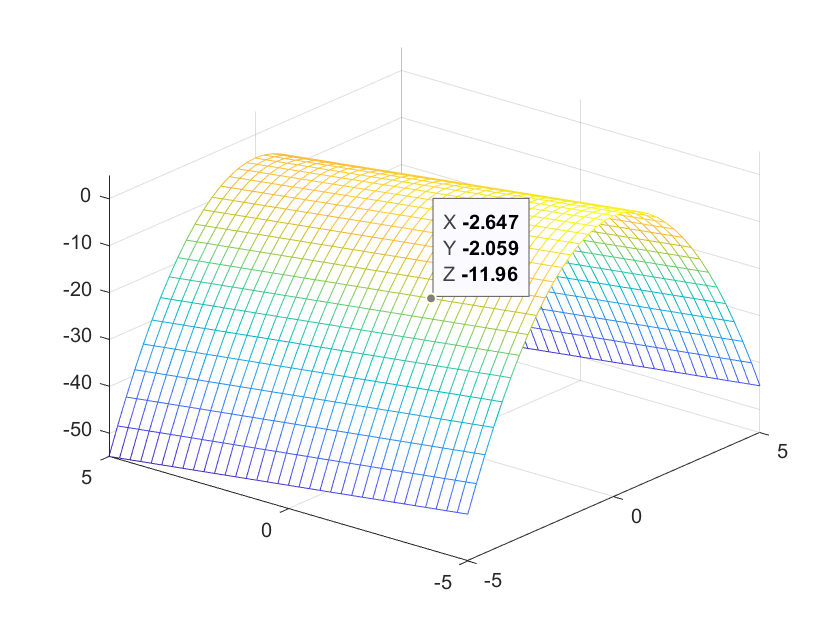

fmesh(subs(N2,parameters,[1 2]))

Квадратичная часть не превосходит 0 (?) => divF < 0 => циклов нет.

Характер неподвижных точек

   k-ая точка (k = 1:3)

k = 1;
static_point = solutions(k,:)

$$static\_point = \left(\begin{array}{cc} 0 & 0 \end{array}\right)$$

lim = 10;

[mu1, mu2] = get_static_point_eigenvalues(F,vars,static_point)

$$substitution = \left(\begin{array}{cc} x & y \end{array}\right)$$

$$F\_new = \left(\begin{array}{c} -e\,x\,\left(x-1\right)-\frac{x\,y}{x+1}\\ \frac{h\,x\,y}{x+1}-y \end{array}\right)$$

$$Jac = \left(\begin{array}{cc} \frac{x\,y}{{\left(x+1\right)}^{2}}-e\,x-e\,\left(x-1\right)-\frac{y}{x+1} & -\frac{x}{x+1}\\ \frac{h\,y}{x+1}-\frac{h\,x\,y}{{\left(x+1\right)}^{2}} & \frac{h\,x}{x+1}-1 \end{array}\right)$$

$$Jac0 = \left(\begin{array}{cc} e & 0\\ 0 & -1 \end{array}\right)$$

$$eigvecs = \left(\begin{array}{cc} 0 & 1\\ 1 & 0 \end{array}\right)$$

$$mu1 = -1$$

$$mu2 = e$$

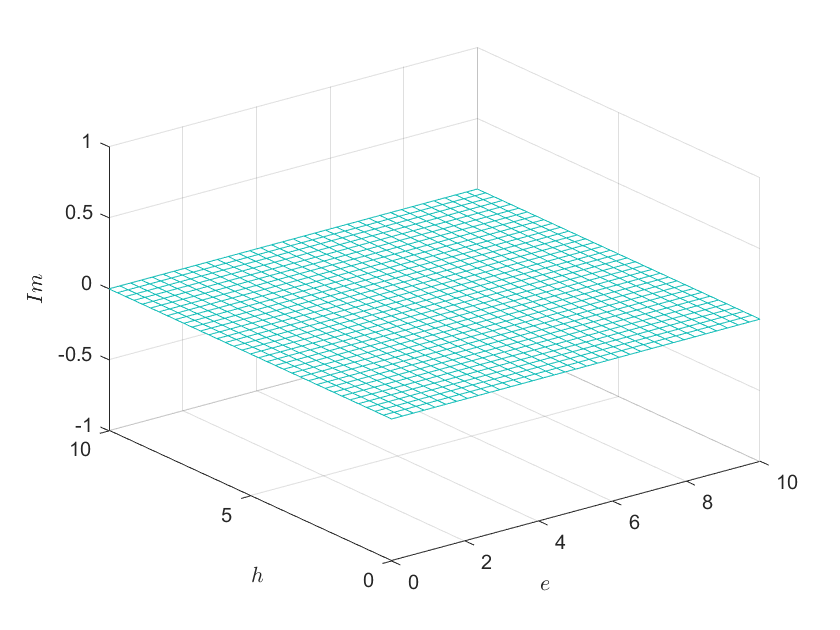


fmesh(imag(mu1),[0 lim]); setplotstyleI('$Im$');
exportgraphics(gcf,'pictures\static_point_1\Im_mu1.pdf');

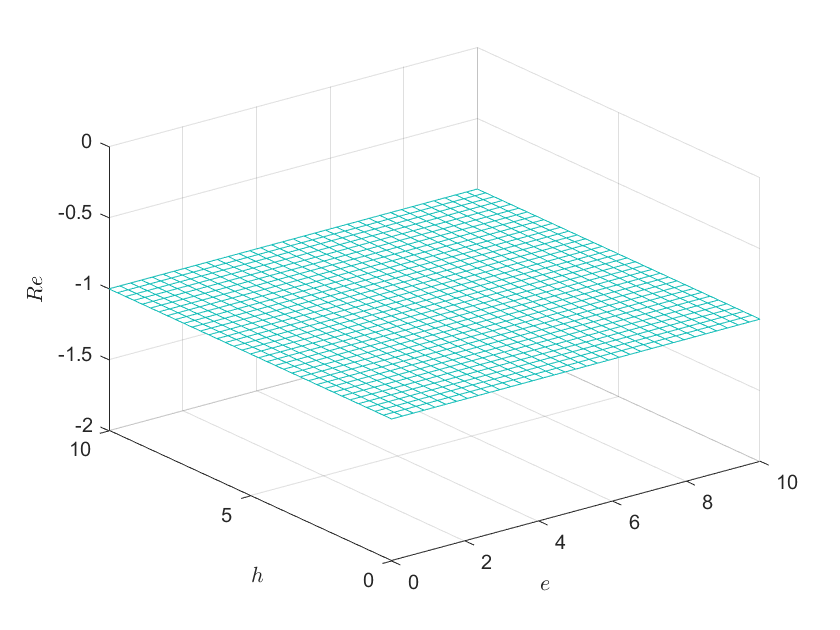

fmesh(real(mu1),[0 lim]); setplotstyleI('$Re$');
exportgraphics(gcf,'pictures\static_point_1\Re_mu1.pdf');

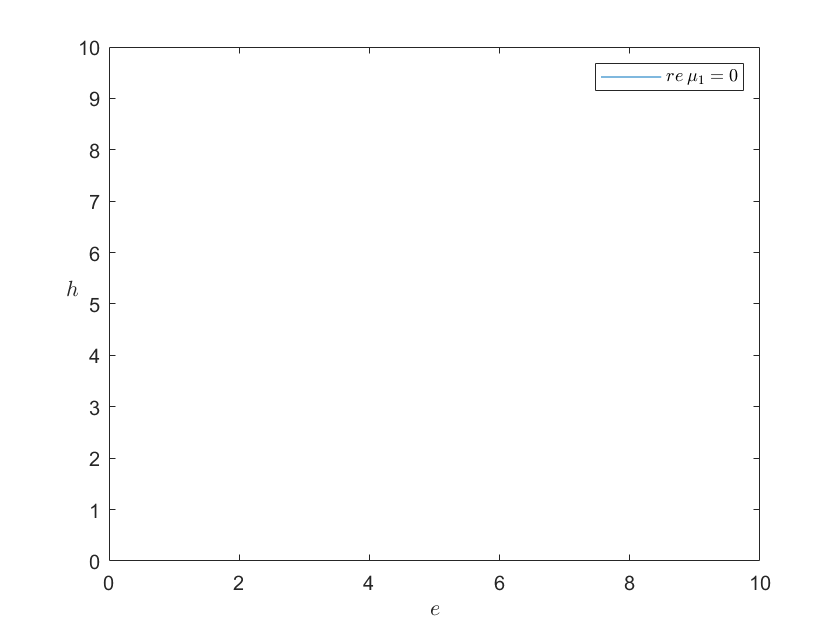

fimplicit(real(mu1) == 0, [0 lim]); setplotstyleII('$re\:\mu_1 = 0$');


fmesh(imag(mu2),[0 lim]); setplotstyleI('$Im$');
exportgraphics(gcf,'pictures\static_point_1\Im_mu2.pdf');

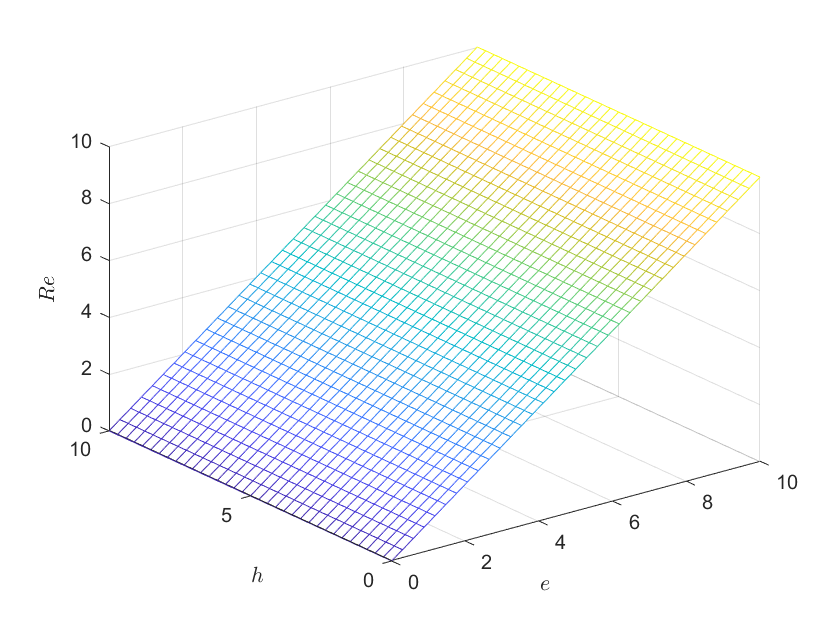

fmesh(real(mu2),[0 lim]); setplotstyleI('$Re$');
exportgraphics(gcf,'pictures\static_point_1\Re_mu2.pdf');

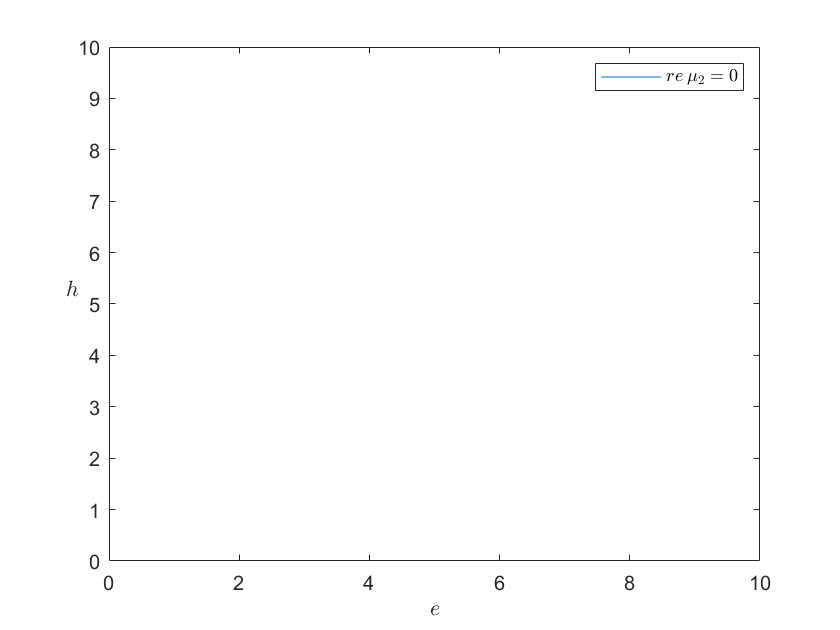

fimplicit(real(mu2) == 0, [0 lim]); setplotstyleII('$re\:\mu_2 = 0$');

k = 2

k = 2

static_point = solutions(k,:)

$$static\_point = \left(\begin{array}{cc} 1 & 0 \end{array}\right)$$

lim = 10;

[mu1, mu2] = get_static_point_eigenvalues(F,vars,static_point)

$$substitution = \left(\begin{array}{cc} x+1 & y \end{array}\right)$$

$$F\_new = \left(\begin{array}{c} -e\,x\,\left(x+1\right)-\frac{y\,\left(x+1\right)}{x+2}\\ \frac{h\,y\,\left(x+1\right)}{x+2}-y \end{array}\right)$$

$$Jac = \left(\begin{array}{cc} \frac{y\,\left(x+1\right)}{{\left(x+2\right)}^{2}}-e\,x-e\,\left(x+1\right)-\frac{y}{x+2} & -\frac{x+1}{x+2}\\ \frac{h\,y}{x+2}-\frac{h\,y\,\left(x+1\right)}{{\left(x+2\right)}^{2}} & \frac{h\,\left(x+1\right)}{x+2}-1 \end{array}\right)$$

$$Jac0 = \left(\begin{array}{cc} -e & -\frac{1}{2}\\ 0 & \frac{h}{2}-1 \end{array}\right)$$

$$eigvecs = \left(\begin{array}{cc} -\frac{1}{2\,e+h-2} & 1\\ 1 & 0 \end{array}\right)$$

$$mu1 = \frac{h}{2}-1$$

$$mu2 = -e$$


fmesh(imag(mu1),[0 lim]); setplotstyleI('$Im$');
exportgraphics(gcf,'pictures\static_point_2\Im_mu1.pdf');

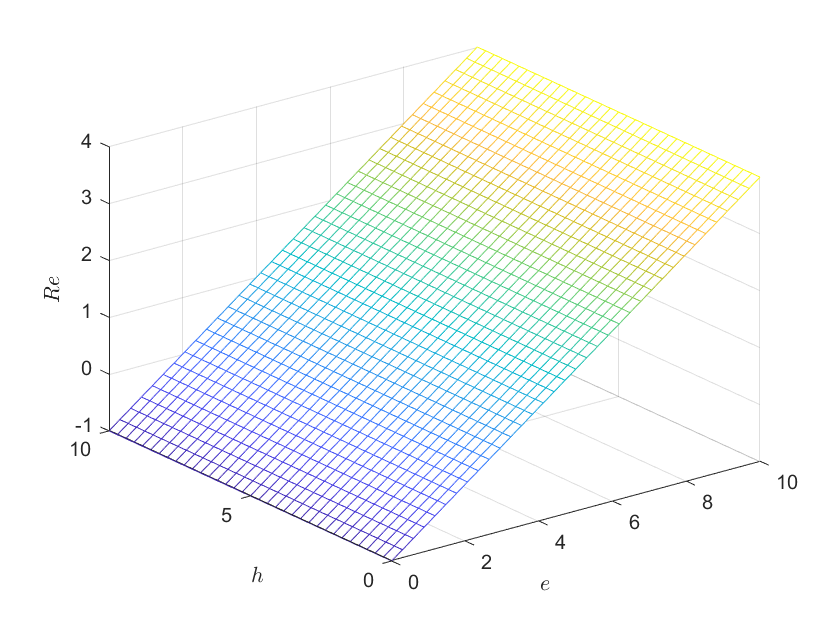

fmesh(real(mu1),[0 lim]); setplotstyleI('$Re$');
exportgraphics(gcf,'pictures\static_point_2\Re_mu1.pdf');

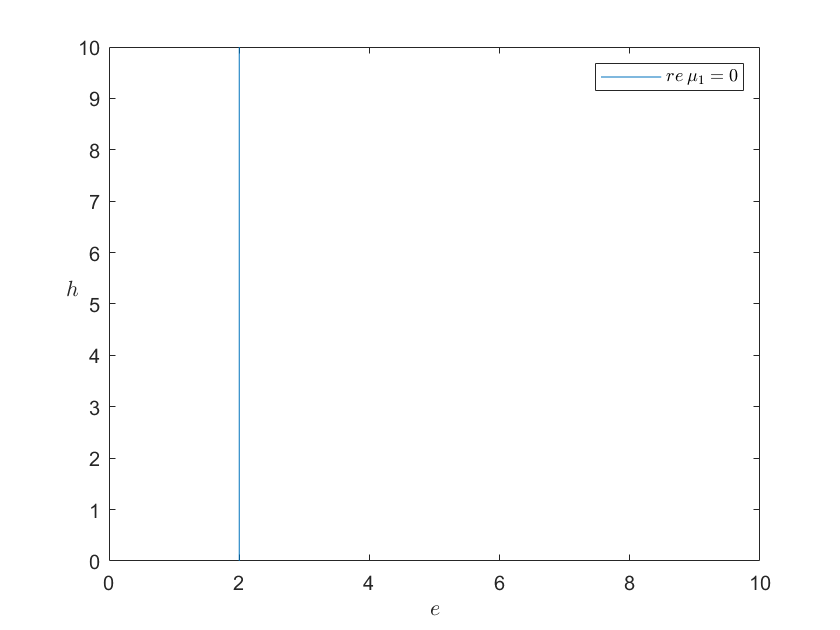

fimplicit(real(mu1) == 0, [0 lim]); setplotstyleII('$re\:\mu_1 = 0$');


fmesh(imag(mu2),[0 lim]); setplotstyleI('$Im$');
exportgraphics(gcf,'pictures\static_point_2\Im_mu2.pdf');

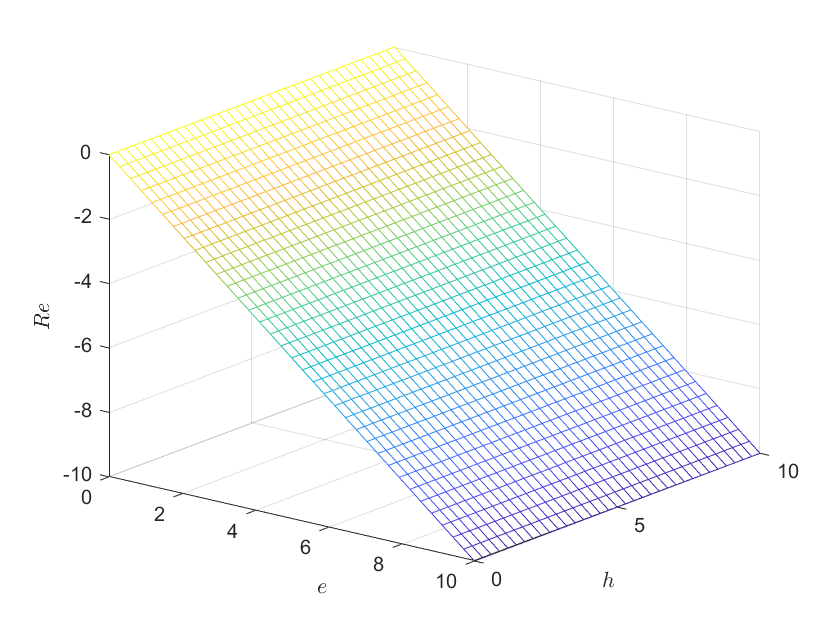

fmesh(real(mu2),[0 lim]); setplotstyleI('$Re$'); view([38 23]);
exportgraphics(gcf,'pictures\static_point_2\Re_mu2.pdf');

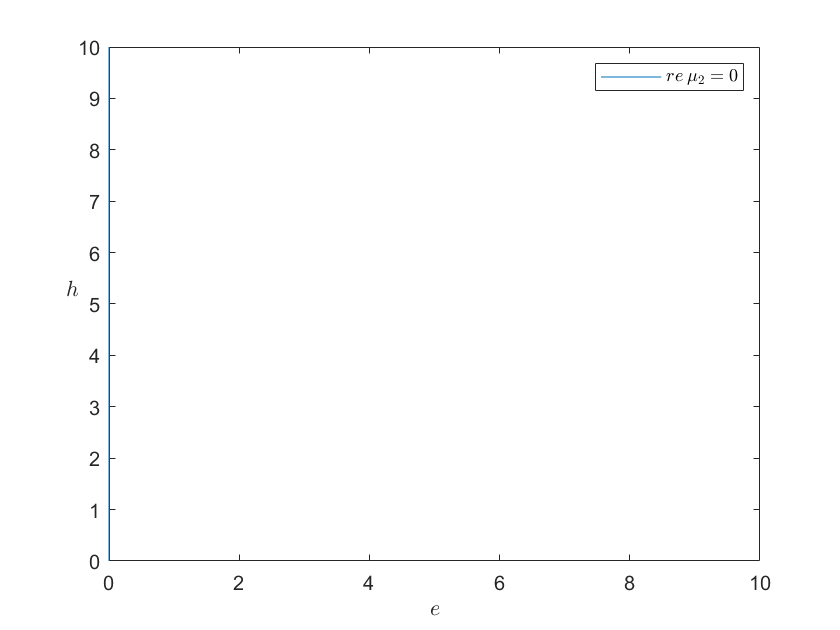

fimplicit(real(mu2) == 0, [0 lim]); setplotstyleII('$re\:\mu_2 = 0$');

k = 3

k = 3

static_point = solutions(k,:)

$$static\_point = \left(\begin{array}{cc} \frac{1}{h-1} & -\frac{2\,e\,h-e\,h^{2}}{h^{2}-2\,h+1} \end{array}\right)$$

lim = 10;

Неподвижная точка $\left(\begin{array}{cc} \frac{1}{h-1} & -\frac{2\,e\,h-e\,h^2}{h^2-2\,h+1} \end{array}\right)$, очевидно, не принаделижит фазовому пространству, при $h < 2$.

elb = 0; erb = lim; hlb = 2; hrb = lim;
bnds = [elb erb hlb hrb];

[mu1, mu2] = get_static_point_eigenvalues(F,vars,static_point)

$$substitution = \left(\begin{array}{cc} x+\frac{1}{h-1} & y-\frac{2\,e\,h-e\,h^{2}}{h^{2}-2\,h+1} \end{array}\right)$$

$$F\_new = \begin{array}{l} \left(\begin{array}{c} -\frac{\left(y-\sigma_{1}\right)\,\left(x+\frac{1}{h-1}\right)}{x+\frac{1}{h-1}+1}-e\,\left(x+\frac{1}{h-1}\right)\,\left(x+\frac{1}{h-1}-1\right)\\ \sigma_{1}-y+\frac{h\,\left(y-\sigma_{1}\right)\,\left(x+\frac{1}{h-1}\right)}{x+\frac{1}{h-1}+1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{2\,e\,h-e\,h^{2}}{h^{2}-2\,h+1} \end{array}$$

$$Jac = \begin{array}{l} \left(\begin{array}{cc} \frac{\sigma_{1}\,\sigma_{3}}{{\sigma_{2}}^{2}}-e\,\sigma_{3}-e\,\left(x+\frac{1}{h-1}-1\right)-\frac{\sigma_{1}}{\sigma_{2}} & -\frac{\sigma_{3}}{\sigma_{2}}\\ \frac{h\,\sigma_{1}}{\sigma_{2}}-\frac{h\,\sigma_{1}\,\sigma_{3}}{{\sigma_{2}}^{2}} & \frac{h\,\sigma_{3}}{\sigma_{2}}-1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=y-\frac{2\,e\,h-e\,h^{2}}{h^{2}-2\,h+1}\\ \sigma_{2}=x+\frac{1}{h-1}+1\\ \sigma_{3}=x+\frac{1}{h-1} \end{array}$$

$$Jac0 = \begin{array}{l} \left(\begin{array}{cc} \frac{\sigma_{1}}{\sigma_{3}}-\frac{e}{h-1}-e\,\left(\frac{1}{h-1}-1\right)-\frac{\sigma_{1}}{\sigma_{2}} & -\frac{1}{\sigma_{4}\,\left(h-1\right)}\\ \frac{h\,\sigma_{1}}{\sigma_{2}}-\frac{h\,\sigma_{1}}{\sigma_{3}} & \frac{h}{\sigma_{4}\,\left(h-1\right)}-1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=2\,e\,h-e\,h^{2}\\ \sigma_{2}={\sigma_{4}}^{2}\,\left(h-1\right)\,\left(h^{2}-2\,h+1\right)\\ \sigma_{3}=\sigma_{4}\,\left(h^{2}-2\,h+1\right)\\ \sigma_{4}=\frac{1}{h-1}+1 \end{array}$$

$$eigvecs = \begin{array}{l} \left(\begin{array}{cc} -\frac{e+\sigma_{1}}{\left(2\,e-e\,h\right)\,\left(h-h^{2}\right)} & -\frac{e-\sigma_{1}}{\left(2\,e-e\,h\right)\,\left(h-h^{2}\right)}\\ 1 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sqrt{e\,\left(-h^{4}+4\,h^{3}-5\,h^{2}+2\,h+e\right)} \end{array}$$

$$mu1 = \frac{e+\sqrt{e\,\left(-h^{4}+4\,h^{3}-5\,h^{2}+2\,h+e\right)}}{h-h^{2}}$$

$$mu2 = \frac{e-\sqrt{e\,\left(-h^{4}+4\,h^{3}-5\,h^{2}+2\,h+e\right)}}{h-h^{2}}$$

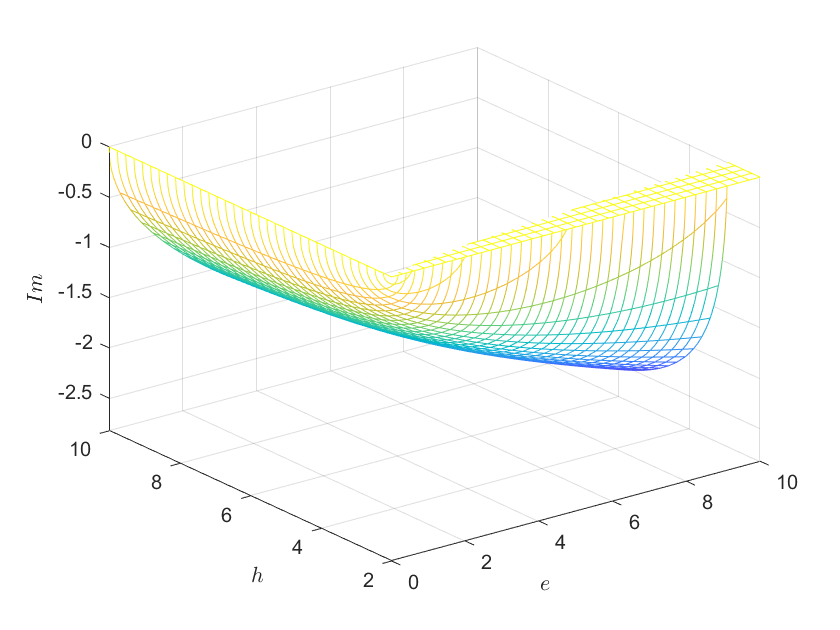


fmesh(imag(mu1),bnds); setplotstyleI('$Im$');
exportgraphics(gcf,'pictures\static_point_3\Im_mu1.pdf');

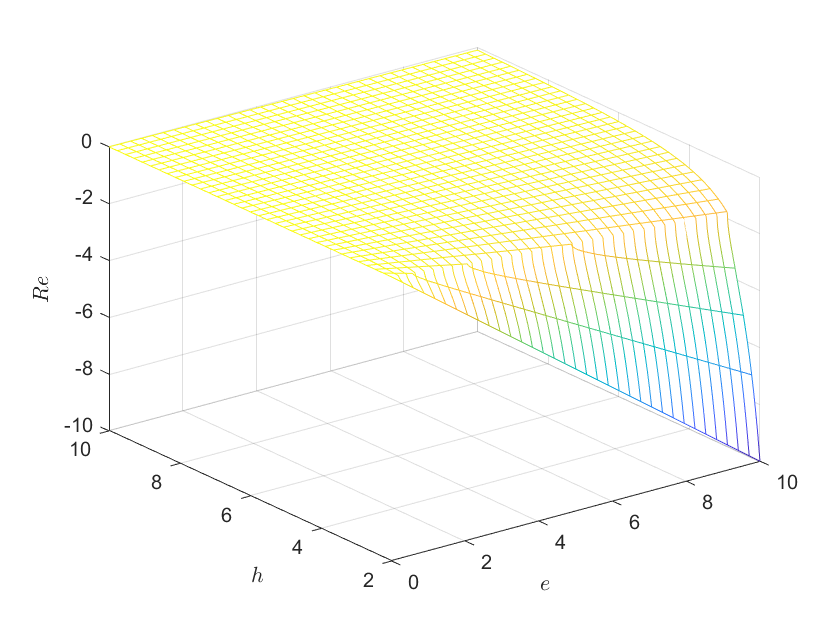

fmesh(real(mu1),bnds); setplotstyleI('$Re$');
exportgraphics(gcf,'pictures\static_point_3\Re_mu1.pdf');

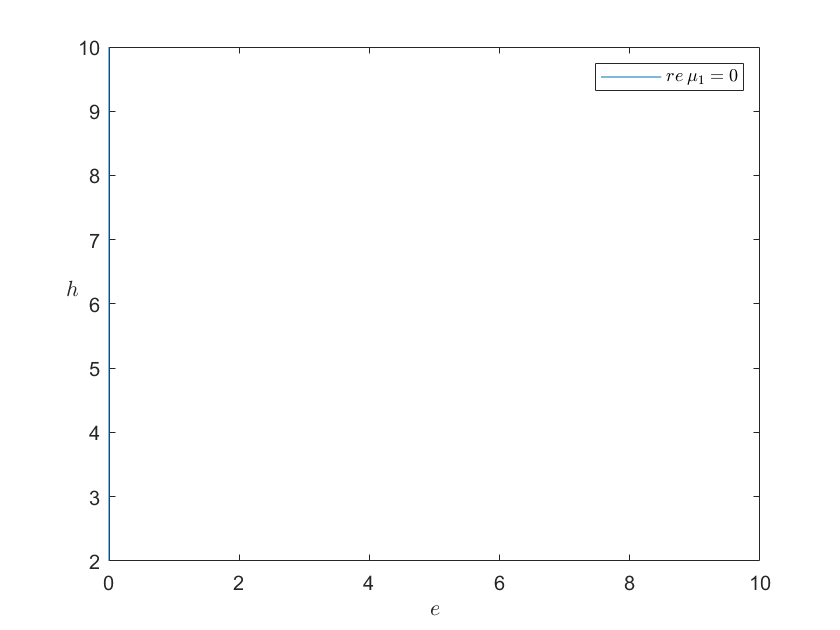

%fplot(real(subs(mu1,e,1)),[hlb hrb]); hold on; fplot(0,[0 lim]); hold off;
fimplicit(real(mu1) == 0, bnds); setplotstyleII('$re\:\mu_1 = 0$');

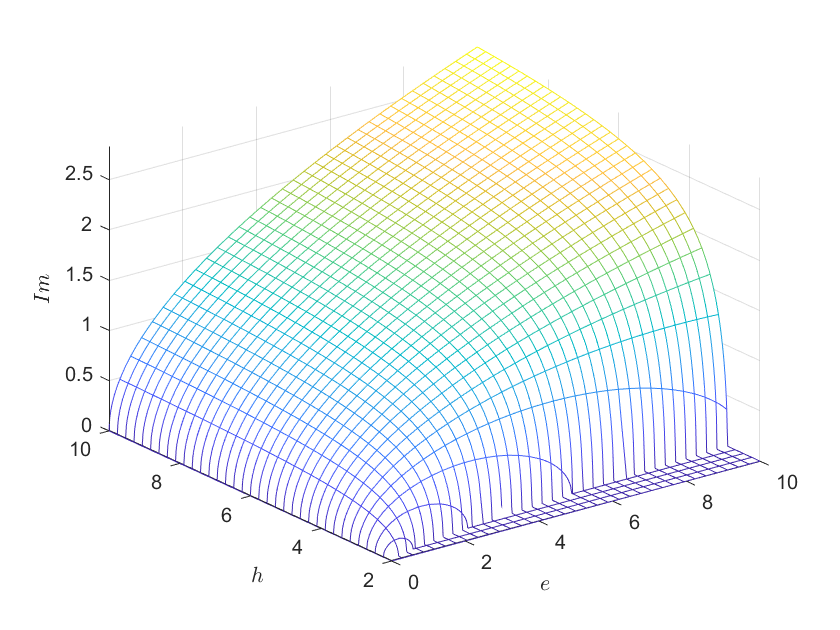


fmesh(imag(mu2),bnds); setplotstyleI('$Im$');
exportgraphics(gcf,'pictures\static_point_3\Im_mu2.pdf');

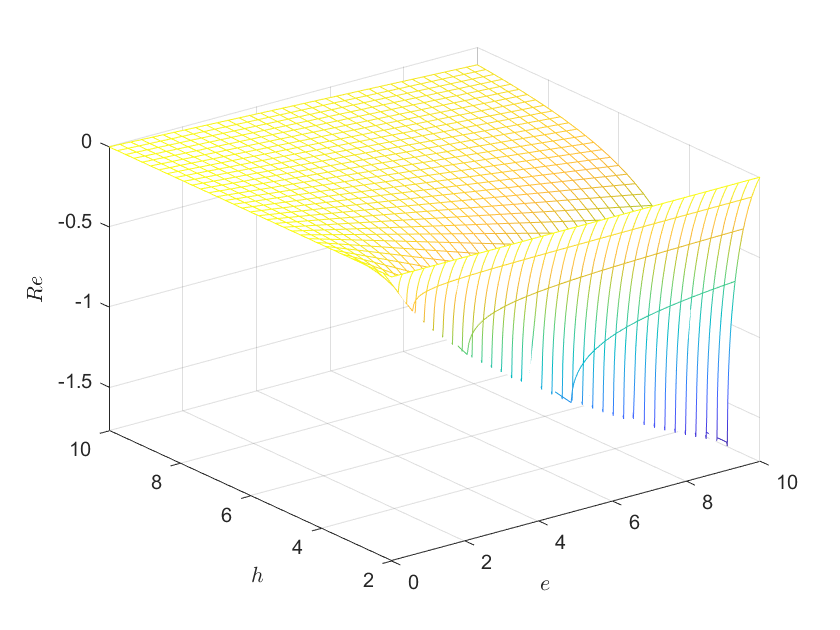

fmesh(real(mu2),bnds); setplotstyleI('$Re$');
exportgraphics(gcf,'pictures\static_point_3\Re_mu2.pdf');

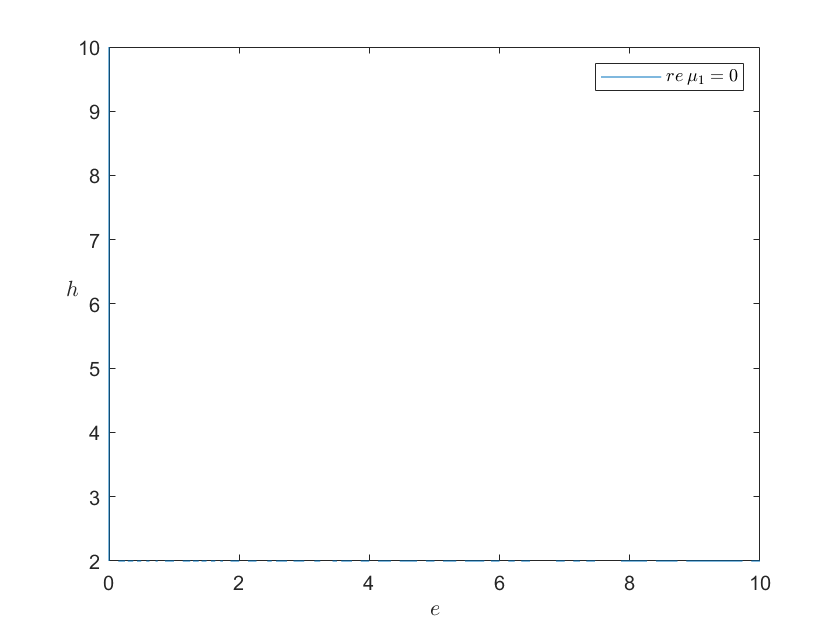

fimplicit(real(mu2) == 0, bnds); setplotstyleII('$re\:\mu_1 = 0$');

Фазовый портрет i

%               e  h
fix_params = [2.5 2.5]; grd = 0.01:0.08:2.01;

stable_point = subs(solutions(3,:), parameters, fix_params)

$$stable\_point = \left(\begin{array}{cc} \frac{2}{3} & \frac{25}{18} \end{array}\right)$$

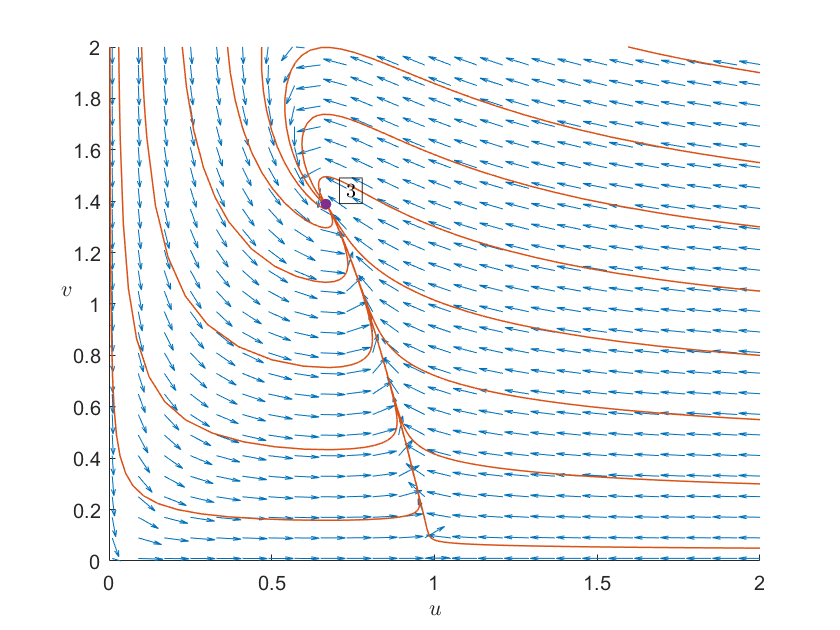


Ffix = subs(F,parameters, fix_params);

X0 = [2.00 2.00 2.00 2.00 2.00 2.00 2.00 2.00 2.00 2.00 0.10 0.03 0.003; 
      0.05 0.30 0.55 0.80 1.05 1.30 1.55 1.90 2.50 3.50 2.00 2.00 2.000];
  
figure;
add_phase_portrait_plot(Ffix,vars,grd,fix_params(1),fix_params(2),X0,stable_point,'\fbox{$3$}');

exportgraphics(gcf,'pictures\phase_portraits\i.pdf');

Фазовый портет ii

%               e  h
fix_params = [1.5 3]; grd = 0.01:0.08:2.01;

stable_point_1 = subs(solutions(3,:), parameters, fix_params)

$$stable\_point\_1 = \left(\begin{array}{cc} \frac{1}{2} & \frac{9}{8} \end{array}\right)$$

stable_point_2 = solutions(2,:)

$$stable\_point\_2 = \left(\begin{array}{cc} 1 & 0 \end{array}\right)$$

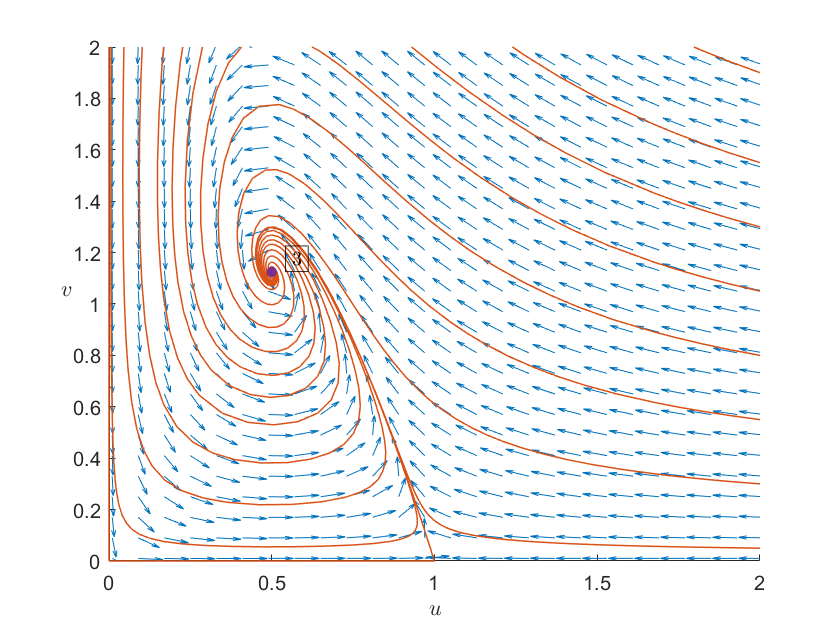


Ffix = subs(F,parameters, fix_params);

X0 = [2.00 2.00 2.00 2.00 2.00 2.00 2.00 2.00 2.00 2.00 2.00 2.00; 
      0.05 0.30 0.55 0.80 1.05 1.30 1.55 1.90 2.50 3.50 6.00 50.0];
  
figure;
add_phase_portrait_plot(Ffix,vars,grd,fix_params(1),fix_params(2),X0,stable_point_1,'\fbox{$3$}');

exportgraphics(gcf,'pictures\phase_portraits\ii.pdf');

Фазовый портет iii

%             e h
fix_params = [1 1]; grd = 0.01:0.08:2.01;

stable_point = solutions(2,:)

$$stable\_point = \left(\begin{array}{cc} 1 & 0 \end{array}\right)$$

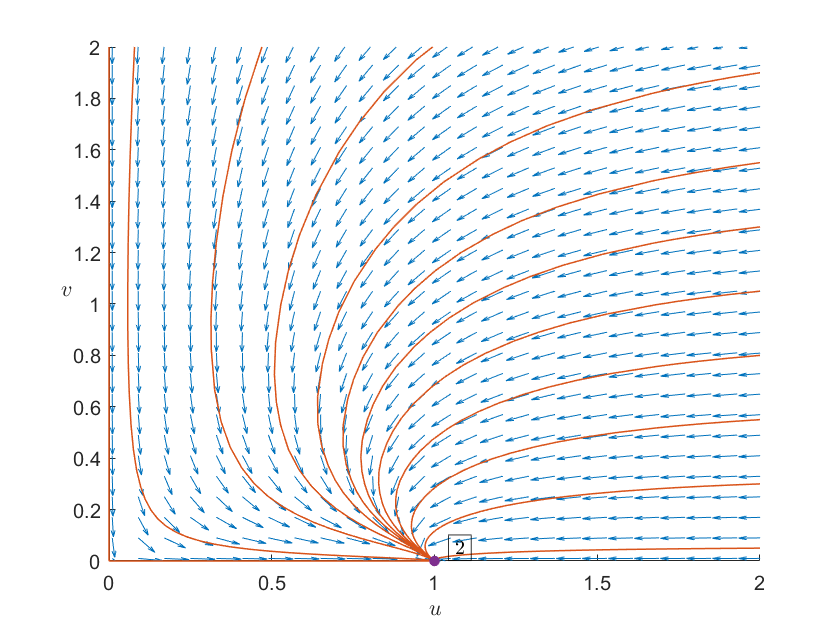


Ffix = subs(F,parameters, fix_params);

X0 = [2.00 2.00 2.00 2.00 2.00 2.00 2.00 2.00 2.00 2.00 2.00 2.00; 
      0.05 0.30 0.55 0.80 1.05 1.30 1.55 1.90 2.50 3.50 6.00 50.0];
  
figure;
add_phase_portrait_plot(Ffix,vars,grd,fix_params(1),fix_params(2),X0,stable_point,'\fbox{$2$}');

exportgraphics(gcf,'pictures\phase_portraits\iii.pdf');

Фазовый портрет iv

%             e h
fix_params = [4 1]; grd = 0.01:0.08:2.01;

seddle_point = solutions(2,:)

$$seddle\_point = \left(\begin{array}{cc} 1 & 0 \end{array}\right)$$

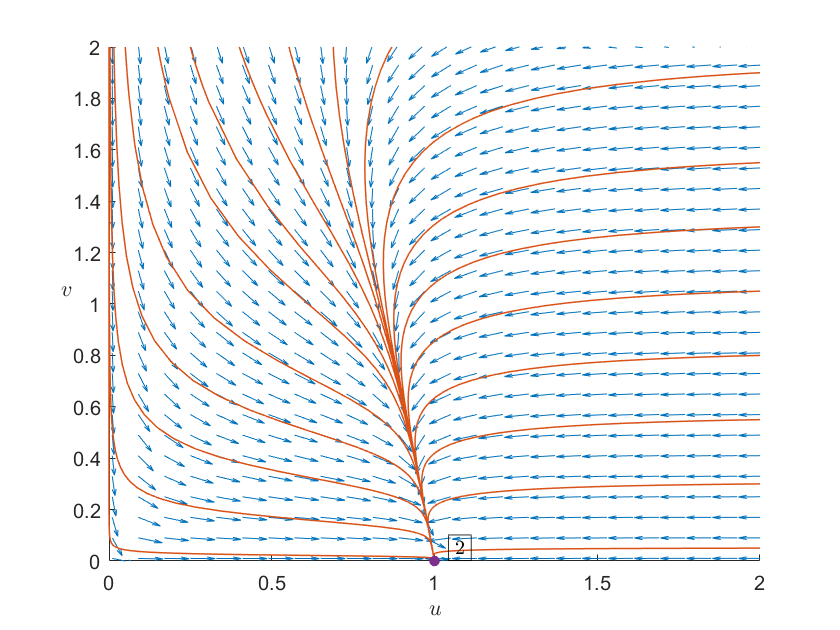


Ffix = subs(F,parameters, fix_params);

X0 = [2.00 2.00 2.00 2.00 2.00 2.00 2.00 2.00 2.00 2.00 2.00 2.00 0.40 0.25 0.15 0.05 0.015 0.003 0.0002; 
      0.05 0.30 0.55 0.80 1.05 1.30 1.55 1.90 2.50 3.50 6.00 50.0 2.00 2.00 2.00 2.00 2.000 2.000 2.0000];
  
figure;
add_phase_portrait_plot(Ffix,vars,grd,fix_params(1),fix_params(2),X0, seddle_point,'\fbox{$2$}');

exportgraphics(gcf,'pictures\phase_portraits\iv.pdf');

Параметрический портрет системы

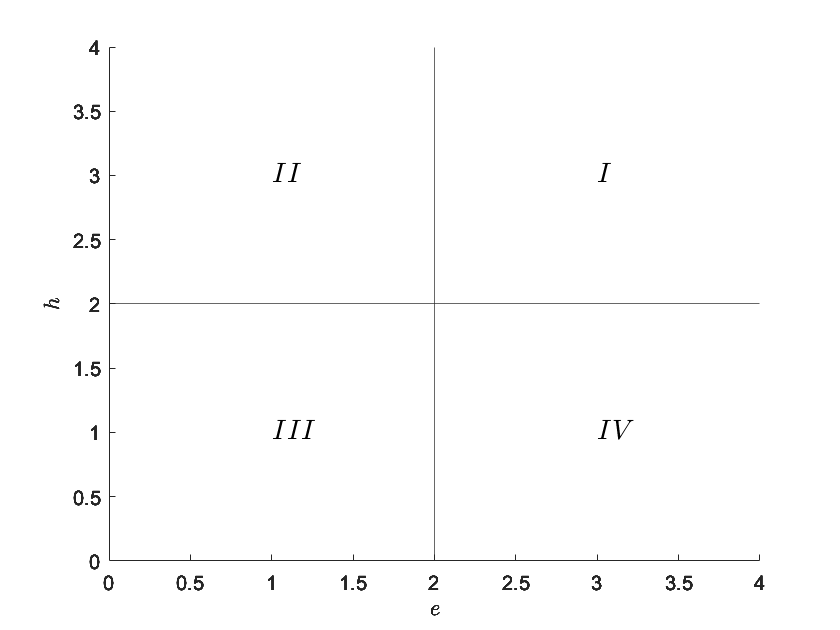

ax = axes('XLim',[0 4],'YLim',[0 4]);
ax.XLabel.Interpreter = 'latex'; ax.YLabel.Interpreter = 'latex';
ax.XLabel.String = '$e$'; ax.YLabel.String = '$h$';
xline(2); yline(2);
text(3,3, '$I$'  ,'Interpreter',"latex",'FontSize',14);
text(1,3, '$II$' ,'Interpreter',"latex",'FontSize',14);
text(1,1, '$III$','Interpreter',"latex",'FontSize',14);
text(3,1, '$IV$' ,'Interpreter',"latex",'FontSize',14);

exportgraphics(gcf,'pictures\phase_portraits\parameters.pdf');

Вспомогательные функции

function res = odefun(t,x,e,f,g,h)
    res =  [e*x(1).*(1-x(1)) - (  x(1).*x(2))./(1+g*x(1));
            -f*x(2)          + (h*x(1).*x(2))./(1+g*x(1))];
end

function [mu1, mu2] = get_static_point_eigenvalues(F,vars,static_point)
    syms x y; %substitution 
    new_vars = [x y];
        %x = u - u* => u = x + u*; \dot u = f(x+u*); v~--- analogously
    substitution = new_vars + static_point
    F_new = subs(F,vars, substitution)
    Jac = jacobian(F_new,new_vars)
    Jac0 = subs(Jac,[x y], [0 0])
    [eigvecs,lambda] = eig(Jac0);
    eigvecs
    mu1 = lambda(1,1); mu2 = lambda(2,2);
end

function add_phase_portrait_plot(Fexmp, vars, grd, e_fix, h_fix, X0, stp, stp_txt)
    hold on;
    
    [X,Y] = meshgrid(grd, grd);
    F1exmp = symfun(Fexmp(1),vars); F2exmp = symfun(Fexmp(2),vars);
    NORM = symfun(sqrt(F1exmp.^2 + F2exmp.^2),vars);
    F1exmp = F1exmp./NORM; F2exmp = F2exmp./NORM;
    Udot = F1exmp(X,Y); Vdot = F2exmp(X,Y);

    q = quiver(X,Y,Udot,Vdot,'AutoScaleFactor',0.7);
    ax = gca; ax.XLim = [0 2]; ax.YLim = [0 2];


    line_col = '#D95319'; line_width = 0.75;
    for cnt = 1:length(X0)
        [t,y] = ode45(@(t,x) odefun(t,x, e_fix,1,1,h_fix),[0 100],X0(:,cnt));
        plot(y(:,1),y(:,2),'LineWidth',line_width,'Color', line_col);
    end
    
    plot(stp(1),stp(2),'Marker','.',"MarkerSize", 18,'Color','#7E2F8E');
    text(stp(1)+0.04,stp(2)+0.05, stp_txt,'Interpreter',"latex");

    setplotstyleIII();

    hold off;
end

function setplotstyleI(z_label)
    hold on;
    ax = gca;
    ax.XLabel.Interpreter = 'latex'; ax.YLabel.Interpreter = 'latex'; ax.ZLabel.Interpreter = 'latex';
    ax.XLabel.String = '$e$'; ax.YLabel.String = '$h$'; ax.ZLabel.String = z_label;
    hold off
end

function setplotstyleII(lgd_text)
    hold on;
    ax = gca;
    ax.XLabel.Interpreter = 'latex'; ax.YLabel.Interpreter = 'latex';
    ax.XLabel.String = '$e$'; ax.YLabel.String = '$h$';
    ax.YLabel.Rotation = 0;
    legend(lgd_text,'Interpreter','latex','AutoUpdate','off');
    hold off;
end

function setplotstyleIII()
    hold on;
    ax = gca;
    ax.XLabel.Interpreter = 'latex'; ax.YLabel.Interpreter = 'latex';
    ax.XLabel.String = '$u$'; ax.YLabel.String = '$v$';
    ax.YLabel.Rotation = 0;
    hold off;
end